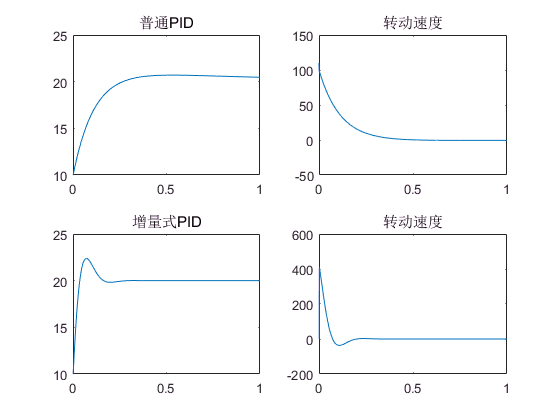

clc
clear 
close all

%% 普通 PID
% PID 参数
kp = 10;
ki = 0.01;
kd = 1;

% PID 控制部分
error = 0;
ts = 0.001;    %采样时间
currentCoordinate(1) = 10;    %当前坐标
time(1) = 0;
move = 0;        %移动距离
sumError = 0;    %误差累计

for k = 1:1000
    time(k+1) = ts*k;
    goalCoordinate = 20;
    currentCoordinate(k+1) = currentCoordinate(k) + move;
    
    lastError = error;              %当前误差
    sumError = sumError+error;      %误差积累
    error = goalCoordinate - currentCoordinate(k+1);
    rate = error - lastError;
    speed(k) = error * kp + sumError * ki + rate * kd;
    move = speed(k) * ts;
end
speed(k+1)=speed(k);
figure(1)
subplot(2,2,1)
plot(time,currentCoordinate)
title('普通PID')
subplot(2,2,2)
plot(time,speed)
title('转动速度')


clear
%% 增量式 PID
% PID 参数
kp = 40;
ki = 0.01;
kd = 1;

% PID 控制部分
error = 0;
error_1 = 0;
error_2 = 0;
xError=[0,0,0];    %存储三个error
speed(1) = 0;
speed(2) = 0;

ts = 0.001;    %采样时间
currentCoordinate(1) = 10;    %当前坐标
time(1) = 0;
move = 0;        %移动距离
sumError = 0;    %误差累计

for k = 1:1000
    time(k+1) = ts*k;
    goalCoordinate = 20;    %目标坐标
    dSpeed = xError(1) * kp + xError(2) * ki + xError(3) * kd;%速度增量
    speed(k+1) = speed(k) + dSpeed;
    
    move = speed(k+1) * ts;
    currentCoordinate(k+1) = currentCoordinate(k) + move;
    %限制一下增长范围
%     if currentCoordinate(k+1) >= 10
%         currentCoordinate(k+1) = 10;
%     else currentCoordinate(k+1) <= -10
%         currentCoordinate(k+1) =-10;
%     end
    error = goalCoordinate - currentCoordinate(k+1);
    
    xError(1) = error - error_1;
    xError(2) = error - 2*error_1 + error_2;
    xError(3) = error;
    error_2 = error_1;
    error_1 = error;
end
subplot(2,2,3)
plot(time,currentCoordinate)
title('增量式PID')
subplot(2,2,4)
plot(time,speed)
title('转动速度')